clear
newcolor = [228 26 28
            55 126 184
            77 175 74
            152 78 163
            255 127 0]/255

newcolor =     0.8941    0.1020    0.1098
    0.2157    0.4941    0.7216
    0.3020    0.6863    0.2902
    0.5961    0.3059    0.6392
    1.0000    0.4980         0


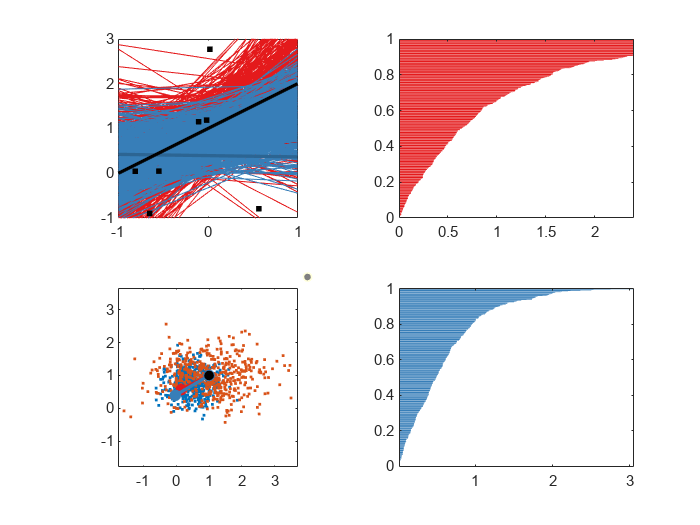

colororder(newcolor);

m = 1;
c = 1;

N = 10;     % Observations per training set
M = 500;   % Number of training sets
C = cvpartition(N*M, 'KFold', M);

rng(1)
xFull = 2*rand(N*M,1) - 1;
yFull = m*xFull + c + 1.5*randn(N*M,1);
    

theta = zeros(2,M);
theta(:,1) = [m;c];
theta_reg = theta;


figure
for i = 2:M
    x = xFull(C.test(i));
    y = yFull(C.test(i));
    
    X = [x ones(N,1)];
    theta(:,i) = (X'*X)\(X'*y);
    theta_reg(:,i) = (X'*X + 3*eye(2))\(X'*y);

    MSE(i,1) = sum( (theta(:,i) - [m; c]).^2 );
    MSE_reg(i,1) = sum( (theta_reg(:,i) - [m; c]).^2 );
    

    subplot(2,2,1)
    p = plot([-1 1], [-1 1; 1 1]*theta(:,1:i), ...
             [-1 1], [-1 1; 1 1]*theta_reg(:,1:i), ...
             [-1 1], [-1 1; 1 1]*theta(:,1),...
             x, y, 'k.','MarkerSize',10);
    for j = 1:i
        p(j).LineWidth = 0.5; p(j).Color = newcolor(1,:);
    end
    for j = i+1:2*i
        p(j).LineWidth = 0.5; p(j).Color = newcolor(2,:);
    end
    p(i).LineWidth = 2; p(i).Color = 0.8*newcolor(1,:);
    p(2*i).LineWidth = 2; p(2*i).Color = 0.8*newcolor(2,:);
    p(2*i+1).LineWidth = 2; p(2*i+1).Color = 'k';
    axis([-1 1 -1 3])
    axis square
    
    subplot(2,2,3)
    pt = plot(theta_reg(1,1:i), theta_reg(2,1:i), '.',...
              theta(1,1:i), theta(2,1:i), '.', ...
              theta(1,[1, i]), theta(2,[1, i]), '-o',...
              theta_reg(1,[1, i]), theta_reg(2,[1, i]), '-o', ...
              m, c, '.');
    pt(1).MarkerSize = 5; 
    pt(2).MarkerSize = 5; 
    pt(3).MarkerSize = 5; pt(3).MarkerFaceColor = newcolor(1,:); pt(3).LineWidth = 2; pt(3).Color = newcolor(1,:);
    pt(4).MarkerSize = 5; pt(4).MarkerFaceColor = newcolor(2,:); pt(4).LineWidth = 2; pt(4).Color = newcolor(2,:);
    pt(5).MarkerSize = 20; pt(5).MarkerFaceColor = 'k'; pt(5).Color = 'k';
    axis([-2 4 -2 4])
    axis square

    subplot(2,2,2)
    bh = barh((1:i)/i, sort(MSE),'FaceColor',newcolor(1,:));
    bh.EdgeColor = 'none';
    axis([0 2.4 0 1])

    subplot(2,2,4)
    bh = barh((1:i)/i, sort(MSE_reg),'FaceColor',newcolor(2,:));
    bh.EdgeColor = 'none';
    axis([0 2.4 0 1])

    drawnow
end

mu = mean(MSE)

mu = 0.9949

mu_reg = mean(MSE_reg)

mu_reg = 0.6170


x = sort(MSE);
x_reg = sort(MSE_reg);

edges = linspace(0, 2.5, 100);
histMSE = histcounts(MSE, edges,'Normalization','pdf');
histMSE_reg = histcounts(MSE_reg, edges,'Normalization','pdf');

y = (1:M)'/M;
fLSQ = @(p, x) (y - gamcdf(x, p(1), p(2)));

p = lsqnonlin(@(p) fLSQ(p, x), [0.9; 0.8]);


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


p_reg = lsqnonlin(@(p) fLSQ(p, x_reg), [1.1; 0.45]);


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


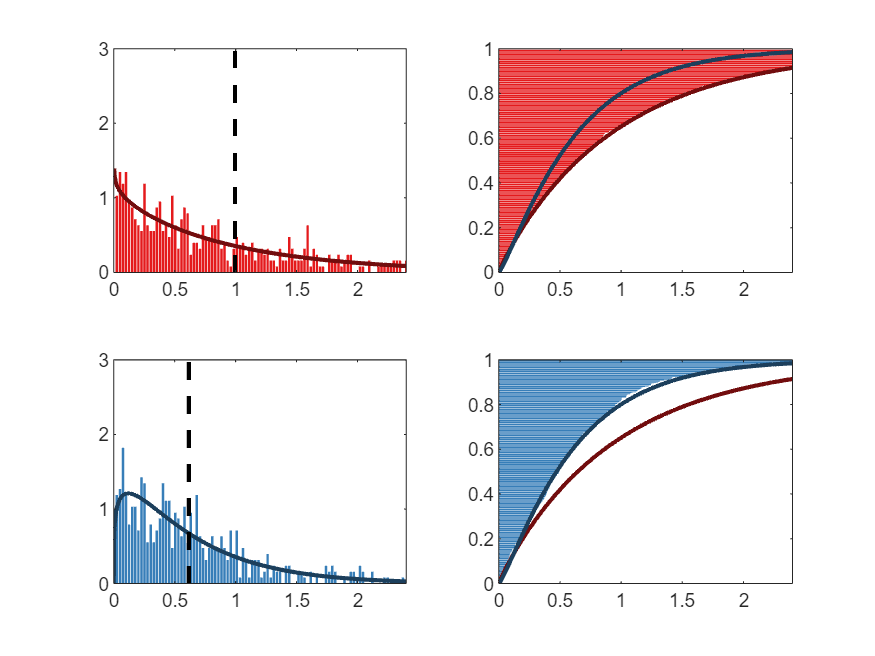


figure
subplot(2,2,2)
bh = barh((1:i)/i, x,'FaceColor', newcolor(1,:));
hold on
plot(x, gamcdf(x, p(1), p(2)), 'Color', 0.5*newcolor(1,:),'LineWidth',2)
plot(x, gamcdf(x, p_reg(1), p_reg(2)),'Color', 0.5*newcolor(2,:),'LineWidth',2)
hold off
bh.EdgeColor = 'none';
axis([0 2.4 0 1])

subplot(2,2,4)
bh = barh((1:i)/i, x_reg,'FaceColor',newcolor(2,:));
hold on
plot(x, gamcdf(x, p(1), p(2)), 'Color', 0.5*newcolor(1,:),'LineWidth',2)
plot(x, gamcdf(x, p_reg(1), p_reg(2)),'Color', 0.5*newcolor(2,:),'LineWidth',2)
hold off
bh.EdgeColor = 'none';
axis([0 2.4 0 1])

subplot(2,2,1)
bh = bar(edges(2:end), histMSE, 'FaceColor', newcolor(1,:));
hold on
plot(x, gampdf(x, p(1), p(2)), 'Color', 0.5*newcolor(1,:),'LineWidth',2)
plot([mu mu], [0 3], 'k--','LineWidth',2)
hold off
bh.EdgeColor = 'none';
axis([0 2.4 0 3])

subplot(2,2,3)
bh = bar(edges(2:end), histMSE_reg, 'FaceColor', newcolor(2,:));
hold on
plot(x_reg, gampdf(x_reg, p_reg(1), p_reg(2)), 'Color', 0.5*newcolor(2,:),'LineWidth',2)
plot([mu_reg mu_reg], [0 3], 'k--','LineWidth',2)
hold off
bh.EdgeColor = 'none';
axis([0 2.4 0 3])

figure
L = 50;
theta_reg_scan = zeros(2,M,L);
lambda_scan = logspace(-1,2,L);
MSE_reg_scan = zeros(M, L);
%p_reg_scan = zeros(L, 2);
for j = 1:L
    for i = 1:M
        x = xFull(C.test(i));
        y = yFull(C.test(i));
        X = [x ones(N,1)];
        theta_reg_scan(:,i,j) = (X'*X + lambda_scan(j)*eye(2))\(X'*y);
        MSE_reg_scan(i,j) = sum( (theta_reg_scan(:,i,j) - [m; c]).^2 );
    end
 %   p_reg_scan(j,:) = lsqnonlin(@(p) fLSQ(p, sort(MSE_reg_scan(:,j))), [1.1; 0.45]);
    mu_scan(:,j) = mean(theta_reg_scan(:,:,j)')';
    sigma_scan(:,:,j) = cov(theta_reg_scan(:,:,j)');
    
end
locus = linspace(0,2*pi)

locus =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099


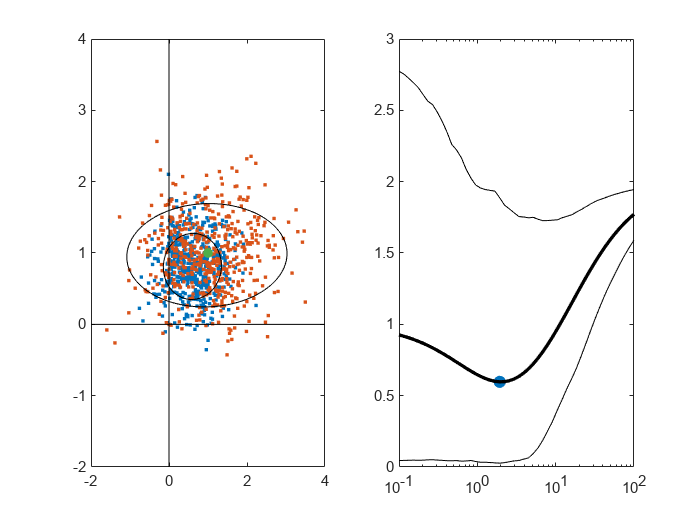

for j = [1:L, L:-1:1]
    subplot(1,2,1)
    ellips0 = 3*sigma_scan(:,:,1)*[cos(locus); sin(locus)];
    ellips = 3*sigma_scan(:,:,j)*[cos(locus); sin(locus)];
    p = plot(theta_reg_scan(1,:,j), theta_reg_scan(2,:,j),'.', ...
             theta(1,:), theta(2,:), '.',...
             theta(1,1), theta(2,1), '.',...
             mu_scan(1,1) + ellips0(1,:), mu_scan(2,1) + ellips0(2,:),'k',...
             mu_scan(1,j) + ellips(1,:), mu_scan(2,j) + ellips(2,:),'k',...
             [-2 4 0 0 0], [0 0 0 -2 4], 'k');
    p(3).MarkerSize = 20; p(3).Color = newcolor(3,:);
    axis([-2 4 -2 4])
    
    subplot(1,2,2)
    p = semilogx(lambda_scan(j), mean(MSE_reg_scan(:,j)),'.', ...
           lambda_scan, mean(MSE_reg_scan),'k',...
           lambda_scan, prctile(MSE_reg_scan, 5),'k',...
           lambda_scan, prctile(MSE_reg_scan, 95),'k',...
           'MarkerSize',25);
    p(2).LineWidth = 2;
    p(3).LineWidth = 0.5;
    p(4).LineWidth = 0.5;
    
    %axis([1e-1 1e2 5e-1 2])
    drawnow
end

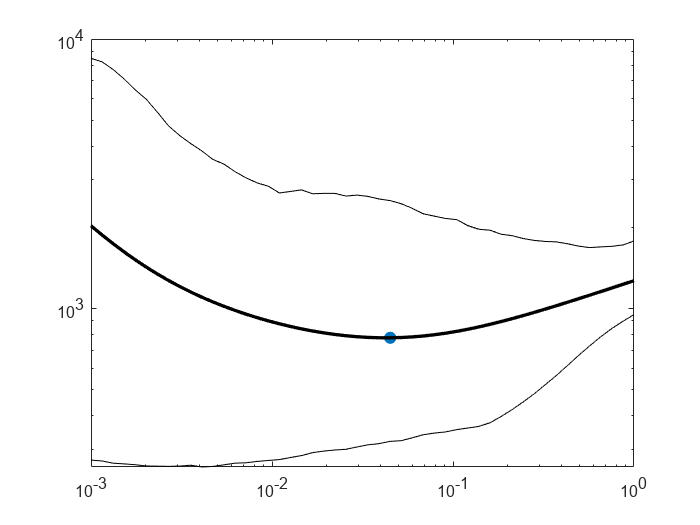

rng(1)
yFullSine = sin(3*xFull) + 0.2*randn(N*M,1);
lambda_scan = logspace(-3,0,L);
P = 7;
xVec = linspace(-1,1)';
XVec = ones(length(xVec),P+1);
for j = 1:P
    XVec(:,j+1) = xVec.^j;
end    

theta_sine = zeros(P+1,M);
theta_reg_sine = theta_sine;

for i = 1:M
    x = xFull(C.test(i));
    y = yFullSine(C.test(i));
    
    Ytest = yFullSine(C.training(i));
    
    X = ones(N,P+1);
    Xtest = ones((M-1)*N,P+1);
    for j = 1:P
        X(:,j+1) = x.^j;
        Xtest(:,j+1) = xFull(C.training(i)).^j;
    end

    theta_sine(:,i) = (X'*X)\(X'*y);
    MSE_sine(i,1) = sum( (Ytest - Xtest*theta_sine(:,i)).^2 );
    
    for j = 1:L
        theta_reg_sine(:,i,j) = (X'*X + lambda_scan(j)*eye(P+1))\(X'*y);
        MSE_reg_sine(i,j) = sum( (Ytest - Xtest*theta_reg_sine(:,i,j)).^2 );
    end
end
figure
[~, I] = min(mean(MSE_reg_sine));
p = loglog(lambda_scan(I), mean(MSE_reg_sine(:,I)),'.', ...
           lambda_scan, mean(MSE_reg_sine),'k',...
           lambda_scan, prctile(MSE_reg_sine, 5),'k',...
           lambda_scan, prctile(MSE_reg_sine, 95),'k',...
           'MarkerSize',25);
p(2).LineWidth = 2;

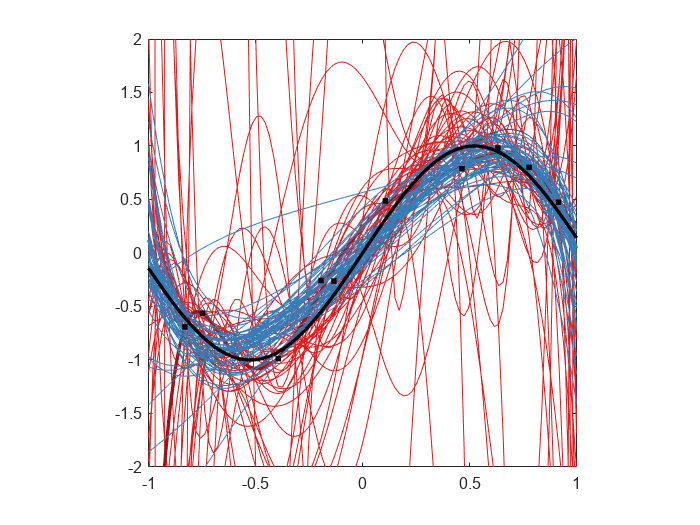

p(3).LineWidth = 0.5;
p(4).LineWidth = 0.5;


figure
for i = 1:M/10
    x = xFull(C.test(i));
    y = yFullSine(C.test(i));
    
    p = plot(xVec, XVec*theta_sine(:,1:i), ...
             xVec, XVec*theta_reg_sine(:,1:i, I),...
             xVec, sin(3*xVec), ...
             x, y, 'k.','MarkerSize',10);
    for j = 1:i
        p(j).LineWidth = 0.5; p(j).Color = newcolor(1,:);
    end
    for j = i+1:2*i
        p(j).LineWidth = 0.5; p(j).Color = newcolor(2,:);
    end
    p(i).LineWidth = 2; p(i).Color = 0.7*newcolor(1,:);
    p(2*i).LineWidth = 2; p(i+1).Color = 0.7*newcolor(2,:);
    p(2*i+1).LineWidth = 2; p(2*i+1).Color = 'k';
    axis([-1 1 -2 2])
    axis square
    

   
    drawnow
end